%%Parameter Values
Ra=2.5;
La=0.05;

Jm= 0.01;
JL= 0.94; %hand calculated value
Bm= 0.001;
BL=0.02; %hand calculated value

Jeff= Jm + JL;
beff= Bm + BL;

% Electrical system to rotational system

s= tf('s');

sys1 = 1/(Jeff*s+beff)

sys1 =
 
        1
  --------------
  0.95 s + 0.021
 
Continuous-time transfer function.
Model Properties


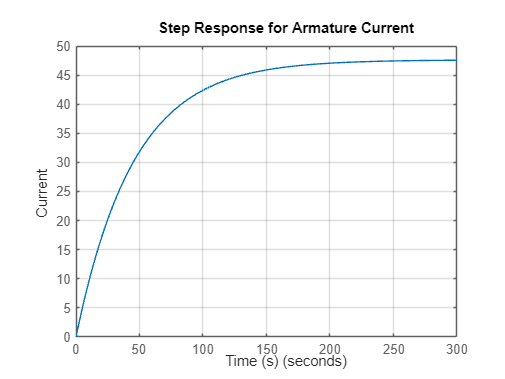


figure;
step(sys1);
grid on;
title('Step Response for Armature Current');
xlabel('Time (s)');
ylabel('Current')


% Rotational system to angular velocity
sys2 = 1/(La*s+Ra)

sys2 =
 
       1
  ------------
  0.05 s + 2.5
 
Continuous-time transfer function.
Model Properties


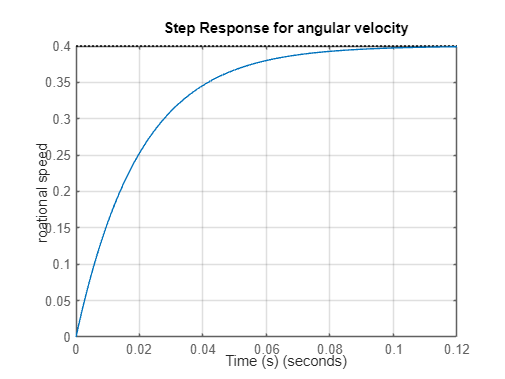


figure;
step(sys2);
grid on;
title('Step Response for angular velocity');
xlabel('Time (s)');
ylabel('roational speed')